AR = 10.69;
ZeroLiftAngle = -3;
%TaperRatio = 0.6;
%b = 118/2

Cr = 13.8

Cr = 13.8000

LiftCurveSlope = 2*pi

LiftCurveSlope = 6.2832


TaperRatio = 0.01:0.01:1

TaperRatio =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


    
b = 1/2*AR*Cr*(1+TaperRatio)

b =    74.4986   75.2362   75.9738   76.7114   77.4490   78.1867   78.9243   79.6619   80.3995   81.1371   81.8747   82.6123   83.3499   84.0875   84.8251   85.5628   86.3004   87.0380   87.7756   88.5132   89.2508   89.9884   90.7260   91.4636   92.2012   92.9389   93.6765   94.4141   95.1517   95.8893   96.6269   97.3645   98.1021   98.8397   99.5773  100.3150  101.0526  101.7902  102.5278  103.2654  104.0030  104.7406  105.4782  106.2158  106.9534  107.6911  108.4287  109.1663  109.9039  110.6415



syms A1 A3 A5 A7 Alpha

MonoPlane = zeros(1,4)

MonoPlane =      0     0     0     0



Theta = zeros(1,4)

Theta =      0     0     0     0



eqn = zeros(1,4)

eqn =      0     0     0     0



for z = 1:1:4
    
    Theta(z) = z*22.5
    
    MonoPlane(z) = LiftCurveSlope*((TaperRatio-1)*cosd(Theta(z))+1)/(4*b)
    
end

Theta =    22.5000         0         0         0


MonoPlane =     0.0081         0         0         0


Theta =    22.5000   45.0000         0         0


MonoPlane =     0.0081    0.0094         0         0


Theta =    22.5000   45.0000   67.5000         0


MonoPlane =     0.0081    0.0094    0.0114         0


Theta =    22.5000   45.0000   67.5000   90.0000


MonoPlane =     0.0081    0.0094    0.0114    0.0136



eqn1 = sind(Theta(1))*(MonoPlane(1)+sind(Theta(1)))*A1 + sind(3*Theta(1))*(3*MonoPlane(1)+sind(Theta(1)))*A3 + sind(5*Theta(1))*(5*MonoPlane(1)+sind(Theta(1)))*A5 + sind(7*Theta(1))*(7*MonoPlane(4)+sind(Theta(1)))*A7 == MonoPlane(1)*sind(Theta(1))

$$eqn1 = \frac{5388037765786231\,A_{1}}{36028797018963968}+\frac{6773707428057779\,A_{3}}{18014398509481984}+\frac{3521738965872891\,A_{5}}{9007199254740992}+\frac{824187841874581\,A_{7}}{4503599627370496}=\frac{1787881621692675}{576460752303423488}$$


eqn2 = sind(Theta(2))*(MonoPlane(2)+sind(Theta(2)))*A1 + sind(3*Theta(2))*(3*MonoPlane(2)+sind(Theta(2)))*A3 + sind(5*Theta(2))*(5*MonoPlane(2)+sind(Theta(2)))*A5 + sind(7*Theta(2))*(7*MonoPlane(4)+sind(Theta(2)))*A7 == MonoPlane(2)*sind(Theta(2))

$$eqn2 = \frac{4563501939320507\,A_{1}}{9007199254740992}+\frac{4683306563220529\,A_{3}}{9007199254740992}-\frac{4803111187120551\,A_{5}}{9007199254740992}-\frac{5112070184628015\,A_{7}}{9007199254740992}=\frac{7667495929601399}{1152921504606846976}$$


eqn3 = sind(Theta(3))*(MonoPlane(3)+sind(Theta(3)))*A1 + sind(3*Theta(3))*(3*MonoPlane(3)+sind(Theta(3)))*A3 + sind(5*Theta(3))*(5*MonoPlane(3)+sind(Theta(3)))*A5 + sind(7*Theta(3))*(7*MonoPlane(4)+sind(Theta(3)))*A7 == MonoPlane(3)*sind(Theta(3))

$$eqn3 = \frac{3891295071463937\,A_{1}}{4503599627370496}-\frac{6603822980499795\,A_{3}}{18014398509481984}-\frac{3380168592907905\,A_{5}}{9007199254740992}+\frac{8483130558963747\,A_{7}}{9007199254740992}=\frac{6045739474847529}{576460752303423488}$$


eqn4 = sind(Theta(4))*(MonoPlane(4)+sind(Theta(4)))*A1 + sind(3*Theta(4))*(3*MonoPlane(4)+sind(Theta(4)))*A3 + sind(5*Theta(4))*(5*MonoPlane(4)+sind(Theta(4)))*A5 + sind(7*Theta(4))*(7*MonoPlane(4)+sind(Theta(4)))*A7 == MonoPlane(4)*sind(Theta(4))

$$eqn4 = \frac{2282532217770187\,A_{1}}{2251799813685248}-\frac{4687994051880131\,A_{3}}{4503599627370496}+\frac{300682729263743\,A_{5}}{281474976710656}-\frac{4933853284559645\,A_{7}}{4503599627370496}=\frac{1966873861436109}{144115188075855872}$$


sol = solve([eqn1, eqn2, eqn3, eqn4], [A1, A3, A5, A7]);

A1 = double(sol.A1)

A1 = 0.0133

A3 = double(sol.A3)

A3 = 0.0014

A5 = double(sol.A5)

A5 = 0.0015

A7 = double(sol.A7)

A7 = 3.4504e-05


delta = (A3/A1)^2+(A5/A1)^2+(A7/A1)^2

delta = 0.0232


e = 1/(1+delta)

e = 0.9773


Theta2 = (0:1:90)

Theta2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



for i=1:length(Theta2)
    
    ClCL(i)=2*(1+TaperRatio)/(pi*A1)/((TaperRatio-1)*cosd(Theta2(i))+1)*(A1*sind(Theta2(i))+A3*sind(3*Theta2(i))+A5*sind(5*Theta2(i))+A7*sind(7*Theta2(i)))
    
    y(i) = cosd(Theta2(i))
    
end

ClCL = 0

y = 1

ClCL =          0    0.0523


y =     1.0000    0.9998


ClCL =          0    0.0523    0.1044


y =     1.0000    0.9998    0.9994


ClCL =          0    0.0523    0.1044    0.1561


y =     1.0000    0.9998    0.9994    0.9986


ClCL =          0    0.0523    0.1044    0.1561    0.2074


y =     1.0000    0.9998    0.9994    0.9986    0.9976


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563


ClCL =          0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947


y =     1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511


ClCL = 1×20
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232


y = 1×20
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455


ClCL = 1×21
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496


y = 1×21
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397


ClCL = 1×22
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739


y = 1×22
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336


ClCL = 1×23
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961


y = 1×23
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272


ClCL = 1×24
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162


y = 1×24
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205


ClCL = 1×25
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344


y = 1×25
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135


ClCL = 1×26
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505


y = 1×26
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063


ClCL = 1×27
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647


y = 1×27
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988


ClCL = 1×28
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770


y = 1×28
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910


ClCL = 1×29
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875


y = 1×29
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


ClCL = 1×30
         0    0.0523    0.1044    0.1561    0.2074    0.2580    0.3078    0.3567    0.4044    0.4508    0.4959    0.5395    0.5815    0.6218    0.6603    0.6968    0.7315    0.7641    0.7947    0.8232    0.8496    0.8739    0.8961    0.9162    0.9344    0.9505    0.9647    0.9770    0.9875    0.9963


y = 1×30
    1.0000    0.9998    0.9994    0.9986    0.9976    0.9962    0.9945    0.9925    0.9903    0.9877    0.9848    0.9816    0.9781    0.9744    0.9703    0.9659    0.9613    0.9563    0.9511    0.9455    0.9397    0.9336    0.9272    0.9205    0.9135    0.9063    0.8988    0.8910    0.8829    0.8746


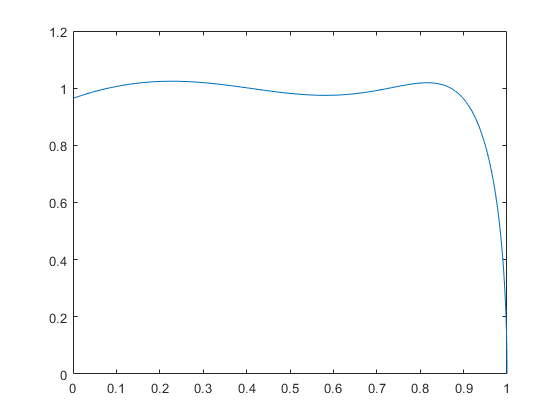


plot(y,ClCL)


% plot(TaperRatio,e)
% xlabel('Taper Ratio, {\it \lambda}')
% ylabel('Oswalds Efficiency, {\it e}')
% grid on



 